# 1.2.10. Фильтрация данных

**Лекция**

## Логические переменные и операции над ними

В лекции 1.2.01 "Типы Данных" логический тип данных был рассмотрен поверхностно. 

Данные логического типа могут принимать только два значения: `true` (логическая 1) и `false` (логический 0). Логические переменные могут быть заданы вручную, так и могут являться результатом сравнений:

L1 = true

L1 = logical
   1


X = 4;
L2 = X==3

L2 = logical
   0


Остальные операторы численного сравнения представлены в таблице:

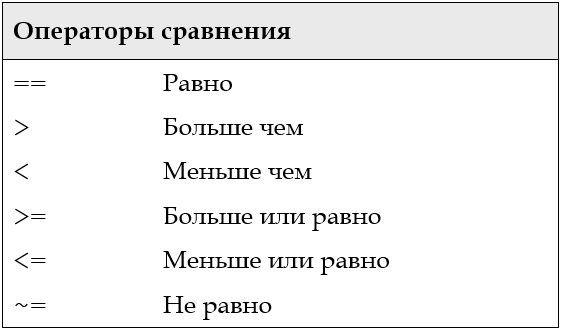

Сравнивать можно не только числа и численные переменные, но и строки (String). Функции сравнения строк представлены в таблице:

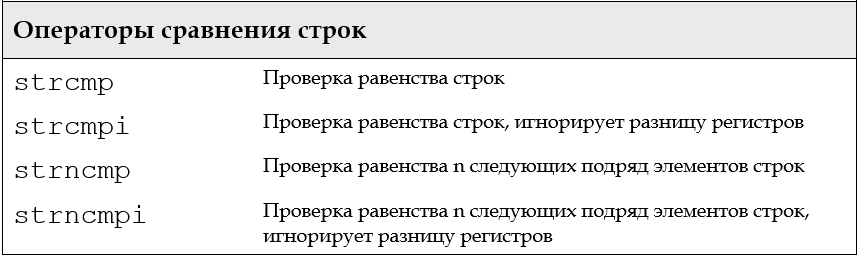

Пример:

Str1 = "добрый"

Str1 = "добрый"

[strcmp(Str1,"добрый"), strcmp(Str1,"Добрый"),strcmpi(Str1,"Добрый")]

ans = 1×3 logical array
   1   0   1


Str2 = "Добрый вечер";
Str3 = "добрый день";
strncmp(Str1,Str3,6)    % проверяет на равенство 6 первых символов

ans = logical
   1


strncmp(Str2,Str3,6)    % без игнорирования регистра

ans = logical
   0


strncmpi(Str2,Str3,6)   % с игнорированием регистра

ans = logical
   1


Над логическими переменными справеливы логические операции и функции, приведённые в таблице:

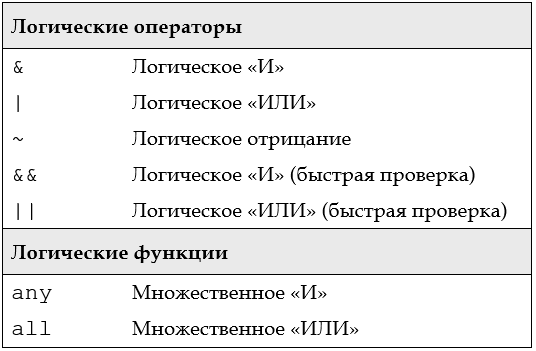

Матрица из логических переменных может быть получена в результате операций сравнения двух числовых матриц одинакового размера: 

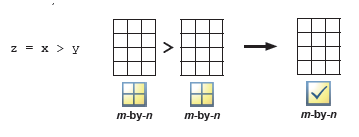

Пример:

M1 = randi([0,12],5,6)

M1 =      8     3     1     6     0     4
     6     3    11     1     9     2
    12    11     0     2    12    10
     9     5    11     9     4     9
     7    10    11    10     8     3


M2 = randi([0,12],5,6)

M2 =      7     3     9     2    12     7
     5     4     2     2     9    12
     1     3     8     8     8     0
     0     2     5     3    12     3
     6     5     5     7    10    12


L3 = M1>M2

L3 = 5×6 logical array
   1   0   0   1   0   0
   1   0   1   0   0   0
   1   1   0   0   1   1
   1   1   1   1   0   1
   1   1   1   1   0   0


То же справедливо и для векторов. 

## Фильтрация данных по условию

Для нахождения данных по заданному условию может использоваться функция find. Она возвращает местонахождение (адреса) удовлетворяющих условию компонент. В случае вектора результатом будет вектор адресов:

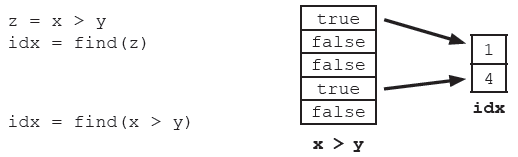

В случае матриц будет возвращено два вектора адресов: по строкам и колонкам:

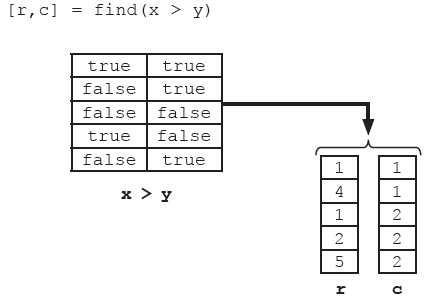

Пример:

L3

L3 = 5×6 logical array
   1   0   0   1   0   0
   1   0   1   0   0   0
   1   1   0   0   1   1
   1   1   1   1   0   1
   1   1   1   1   0   0


[r,c] = find(L3);
[r,c]

ans =      1     1
     2     1
     3     1
     4     1
     5     1
     3     2
     4     2
     5     2
     2     3
     4     3


Чтобы найти количество удовлетворяющих условию элементов в матрице по столбцам или строкам (в зависимости от выбранного параметра `Dimension`) используется уже рассмотренная ранее функция `sum`, а для поиска общего количества удовлетворяющих условию компонент используется команда `nnz`:

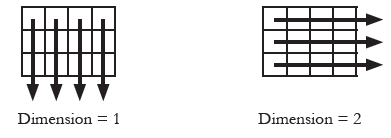

sum(L3)     % по столбцам, по умолчанию

ans =      5     3     3     3     1     2


sum(L3,2)   % по строкам, Dimension = 2

ans =      2
     2
     4
     5
     4


nnz(L3)     % общее количество удовлетворяющих условию компонент

ans = 17

## Логическое индексирование

В лекции 1.2.01 "Типы Данных" в общих чертах было рассказано о логическом индексировании. 

Логическое индексирование - это выделение той части вектора, которая удовлетворяет заданному условию. Для начала следует получить логический вектор, который в свою очередь подается как индекс. Принцип работы показан на схемах ниже.

Индексирование с использованием функции `find`:

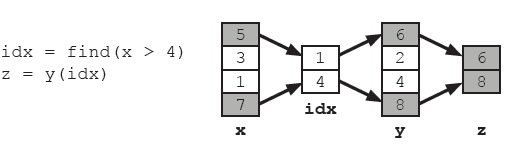

X1 = M1(2,:)

X1 =      6     3    11     1     9     2


F1 = find(X1>5)

F1 =      1     3     5


X1(F1)

ans =      6    11     9


Логический вектор можно задавать напрямую: 

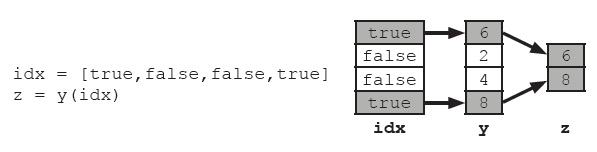

L4 = [true, false, true, true, false, false];
X1(L4)

ans =      6    11     1


В качестве адресов можно использовать результат сравнения напрямую:

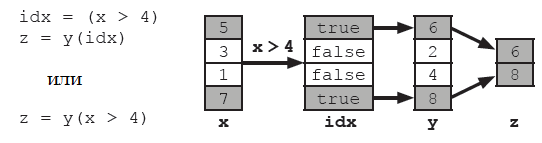

X1(X1>5)

ans =      6    11     9
